# Generate OFDM Samples

This script creates a file with the IQ samples of an OFDM mapped message. 

For generating the OFDM signal, we are going to reuse the code that was developped in the first module. However, in this case the generated signal will be saved in a file "***OFDM_IQ_samples_simulation.mat***" to later be transmitted and received through two different ADALM Plutos.

#### Sampling Parameters

Fs=1*1e5; % Sampling frequency (MHz)
Ts = 1/Fs; % Sampling time

#### OFDM Parameters

We define the necessary parameters to generate the OFDM signal. 

Firstly, *N_OFDM* represents the **FFT size**, which determines the total number of subcarriers in the OFDM system. *Ng*, this specifies the **cyclic prefix (CP) length**, calculated as one-eighth of the total OFDM symbol length. Then, as number of **pilot subcarriers** used in the OFDM frame, we define *num_pilots* with an amplitude (*P_ampl*) of 1. Finally, the variables (*fg_1* and *fg_2*)  represent the number of frequencies in the OFDM spectrum used as guardbands, at the beginning and end part of the signal.

%N_OFDM=1024; %case 1 (Rx_samples_def_less.mat)
N_OFDM=2048; % case 2 (Rx_samples_def_less2.mat)
Ng=1/8*N_OFDM;
num_pilots=0; %45
P_ampl=1; 
fg_1=171; %171
fg_2=172; %172

The following steps are the same as in the first module. We start by calculating the number of data or efective subcarriers  (*N_OFDM_ef*) and the number of OFDM symbols that we want to simulate (*N_symb*). Then, with this information, we can calculate the number of real samples in the simulation (*n_samples*).

N_OFDM_ef=N_OFDM-fg_1-fg_2-num_pilots;
N_symb=100; 
n_samples=N_symb.*N_OFDM_ef; 

fprintf('number of subcarriers for frequency guards: %f, %f  1/%f\n',fg_1,fg_2,N_OFDM/Ng);

number of subcarriers for frequency guards: 171.000000, 172.000000  1/8.000000


fprintf('%f pilots with amplitude=%f\n',num_pilots,P_ampl);

0.000000 pilots with amplitude=1.000000


Now we can create the vector of pilots. We start specifying the position for the 45 pilots (*P*). We calculate the number of subcarriers between a pilot and the next one (*delta*). And then, we can create the vector (*P*) that contains the position of these pilots, and already has space between two consecutive pilots to introduce the data subcarriers.

delta=floor(N_OFDM_ef/num_pilots)+1;
P=[delta:delta:num_pilots*delta];

We already have everything prepared to create the OFDM signal. For doing this process, first we must create a zero vector with the proper dimensions, so, since the number of symbols we want to simulate is *N_symb* and each symbol has *N_OFDM* total subcarriers (including both the effective ones and the guard bands) plus the number of samples chosen for the cyclic prefix (*Ng*):

signal=zeros(1,N_symb*(N_OFDM+Ng));                         

The next step is to fill the zero signal created above. So, firstly, for each one of the symbols we want to simulate, we need to generate a QPSK sequence in base band (*qpsk*). Secondly, in the pilot positions of the QPSK sequence created before, we have to normalize the amplitude to the one chosen for these pilots (*P_amp*l). As next step, we create an additional qpsk signal (*qpsk_ini*), with zero in all de *N_OFDM* positions, and we add the *qpsk* sequence created before, that already has the proper amplitude for the pilots, between the guard bands. At this point, we already have the transmission signal created (*qpsk_ini*) with all the subcarriers, including the pilot ones and guard bands, modulated with QPSK. So now, we can create the OFDM signal applying the IFFT and normalizing the result multipying by the factor  *N_OFDM, *getting in this way the first *ofdm* signal. Now, we need to add the cyclic prefix, for doing this we rewrite the same signal *ofdm *adding to the initial part the cyclic prefix, that as we have previously explained, consists of the last *Ng* subcarriers. Finally, the last step requires filling the general zero signal created before (*signal*), with the OFDM signal (*ofdm*) calculated in the loop, for each simulated symbol (*symb*), in its proper position.

for (symb=1:N_symb)   

    i=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    q=sign(rand(1,N_OFDM_ef+num_pilots)-0.5);
    qpsk=i+j*q;

    for index_p=1:num_pilots  
        qpsk(P(index_p)+1)=P_ampl; 
    end
    
    qpsk_ini=zeros(1,N_OFDM);
    %We add the fftshift to ensure a proper representation by the reception
    %of the pluto
    qpsk_ini(fg_1+1:N_OFDM-fg_2)=qpsk;%fftshift(qpsk);

    ofdm=N_OFDM.*ifft(fftshift(qpsk_ini),N_OFDM);
    ofdm=[ofdm(N_OFDM-Ng+1:N_OFDM),ofdm];

    signal(1,(symb-1)*(N_OFDM+Ng)+1:symb*(N_OFDM+Ng))=ofdm;


end 

txSamples=signal;

Finally, once we have the signal created, we can represent its spectrum, to verify that the OFDM signal that we have generated looks great.  Analyzing the following graph, it is clear that we get the spectrum that we were expecting, which means that the generated OFDM signal should be correct.

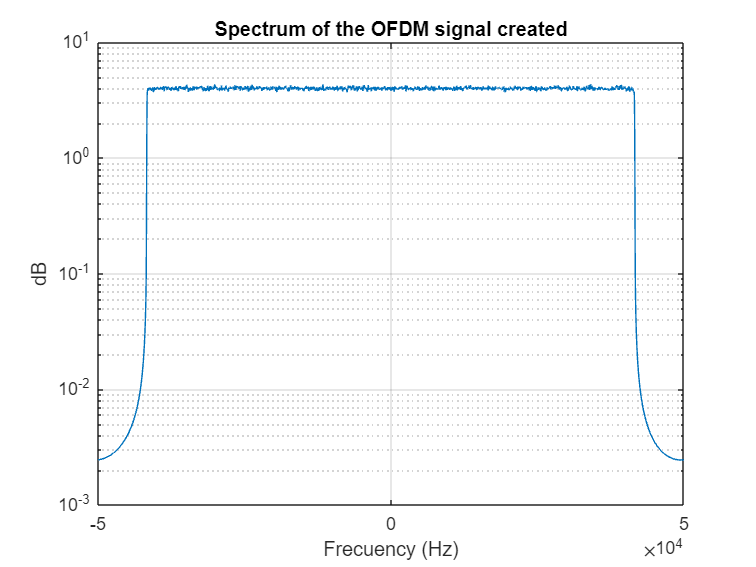

[p,f] = pspectrum(txSamples);
new_f=f./pi*Fs/2;
semilogy(new_f,(p))
grid on
title('Spectrum of the OFDM signal created')
xlabel("Frecuency (Hz)")
ylabel('dB')

It's also interesting to represent the signal in time, where we again reafirm our hypothesis that the generated signal seems appropiate, since we are getting in time what we were looking for:

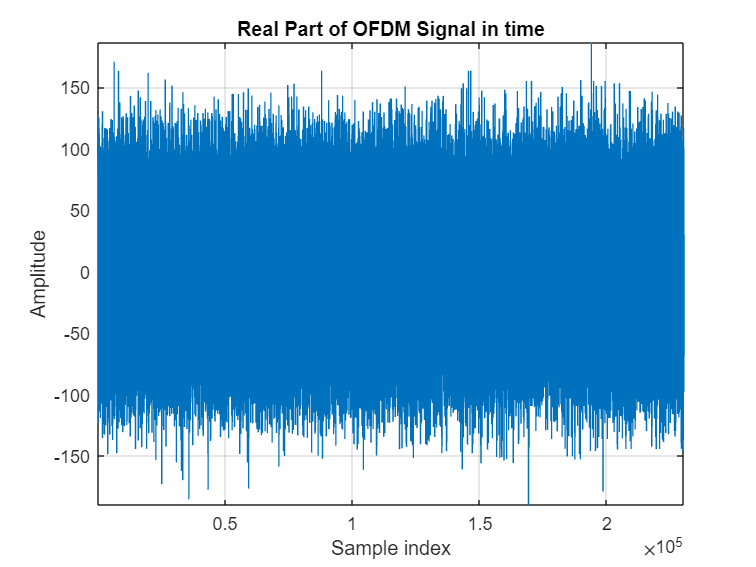

% Plot real part of the OFDM signal
figure
plot(real(txSamples))
grid on
title("Real Part of OFDM Signal in time")
axis tight;
xlabel("Sample index")
ylabel("Amplitude")

#### Build burst signal

Now, like we did for the BPSK signal, we need to modify the signal so it's bursted. This is way it's easier to *visually* know when the frame starts and ends. Therefore, this means that we are going to add some zeros at the beginning and at the end of the each frame, as we can see in the next graph, where we encount some zeros, the signal, and some zeros again.

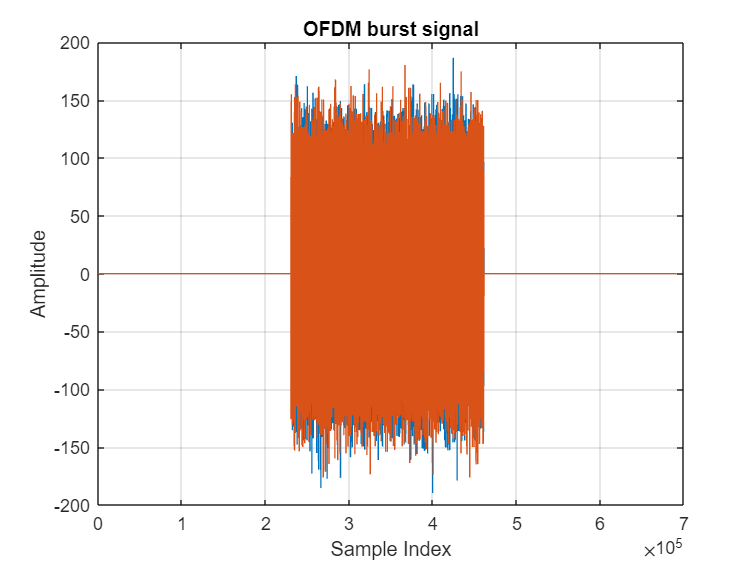

samplesPerFrame = numel(txSamples);   % Total number of samples
frameDuration   = samplesPerFrame*Ts; % Frame duration (Number of samples per frame * sampling time)

% Append zeros at the start and end to create bursted signal
burstedSignal   = [complex(zeros(samplesPerFrame,1));txSamples.';complex(zeros(samplesPerFrame,1))]; 

% Plot bursted signal
figure
plot ([real(burstedSignal), imag(burstedSignal)])
grid on
title("OFDM burst signal")
xlabel("Sample Index")
ylabel("Amplitude")

#### Build and save IQ samples

Finally, the last part we have left consists of preparing the generated OFDM signal for storage and transmission, by organizing it into a structured format (*timeseries*) along with metadata (*userData*). 

This step is exactly the same as we did in the previous module with the BPSK signal. Basically, this ensures the signal and its relevant information can be easily accessed and reused for transmission, debugging, or analysis. Now, in the next file "***OFDM_Transmitter***" we are going to just send the data stored in the new generated file "***OFDM_IQ_samples_simulation_less2***".

% Make IQ samples as a time series
IQSamples = timeseries(burstedSignal,"Name","IQSamples");

% Add userData
userData.fs                 = Fs;
userData.signalDuration     = frameDuration; 
userData.modulation         = "OFDM";
userData.samplesPerSymbol   = N_OFDM + Ng;
userData.numBits            = length(signal);
IQSamples.DataInfo.UserData = userData;

% Save file
%fileName = "OFDM_IQ_samples_simulation_less2";
save(fileName, "IQSamples");